SIR dynamics on ER, small-world, and BA networks

Run this live script from the package folder so the helper functions are on the MATLAB path.

clearvars; close all; clc;

%DEMO_SIR_COMPARE_TOPOLOGIES SIR dynamics on ER / WS / BA graphs.
%
% Uses a discrete-time synchronous approximation:
%   S -> I with probability 1 - (1-beta)^m
%   I -> R with probability mu

rng(7);

n = 1000;
kbar = 6;

Ger = make_er_graph(n, kbar / (n - 1));
Gws = make_ws_graph(n, kbar / 2, 0.05);
Gba = make_ba_graph(n, 5, kbar / 2);


Time series at one parameter choice

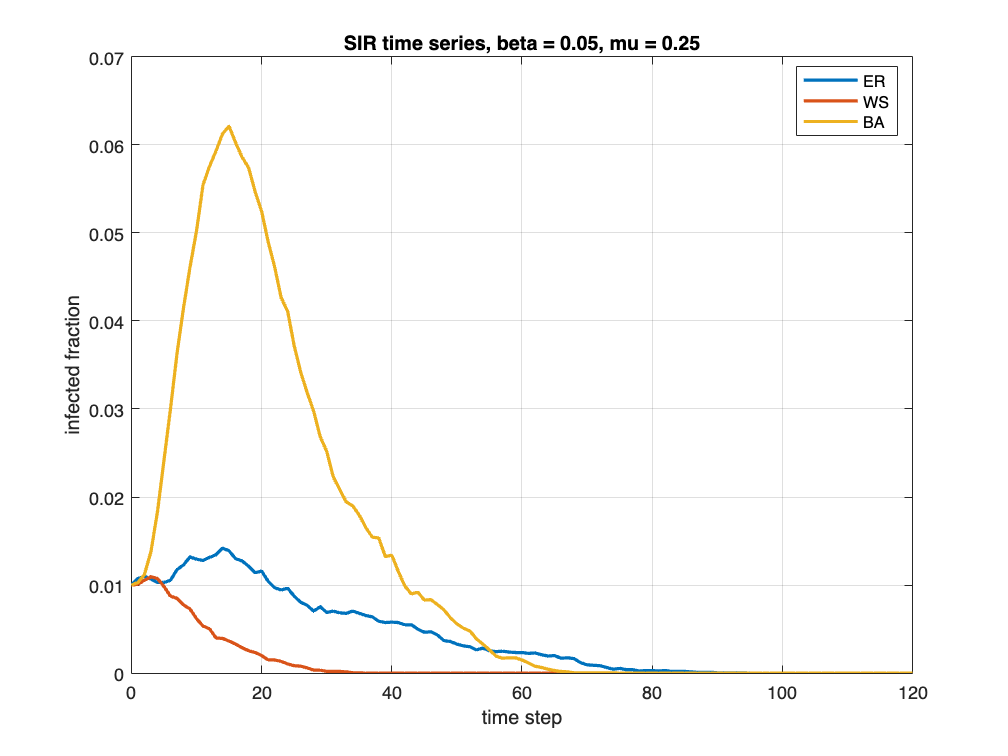

beta = 0.05;
mu = 0.25;
Tmax = 120;
runs = 20;
seedFrac = 0.01;

Ier = zeros(Tmax + 1, runs);
Iws = zeros(Tmax + 1, runs);
Iba = zeros(Tmax + 1, runs);

Rer = zeros(Tmax + 1, runs);
Rws = zeros(Tmax + 1, runs);
Rba = zeros(Tmax + 1, runs);

for r = 1:runs
    [~, I, R] = simulate_SIR_discrete(Ger, beta, mu, Tmax, seedFrac, 'random');
    Ier(:, r) = I;
    Rer(:, r) = R;

    [~, I, R] = simulate_SIR_discrete(Gws, beta, mu, Tmax, seedFrac, 'random');
    Iws(:, r) = I;
    Rws(:, r) = R;

    [~, I, R] = simulate_SIR_discrete(Gba, beta, mu, Tmax, seedFrac, 'random');
    Iba(:, r) = I;
    Rba(:, r) = R;
end

figure('Name', 'SIR infected fraction over time');
plot(0:Tmax, mean(Ier, 2), 'LineWidth', 1.8);
hold on;
plot(0:Tmax, mean(Iws, 2), 'LineWidth', 1.8);
plot(0:Tmax, mean(Iba, 2), 'LineWidth', 1.8);
hold off;
xlabel('time step');
ylabel('infected fraction');
title(sprintf('SIR time series, beta = %.2f, mu = %.2f', beta, mu));
legend('ER', 'WS', 'BA', 'Location', 'best');
grid on;

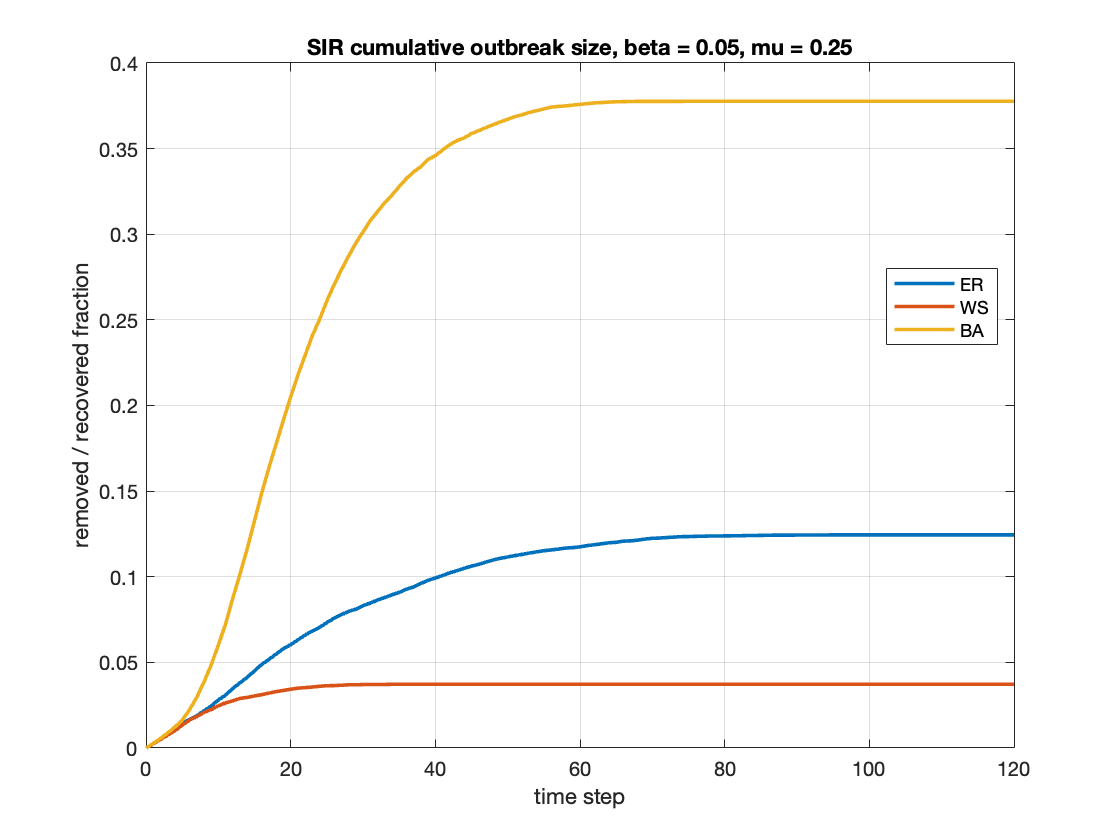


figure('Name', 'SIR removed fraction over time');
plot(0:Tmax, mean(Rer, 2), 'LineWidth', 1.8);
hold on;
plot(0:Tmax, mean(Rws, 2), 'LineWidth', 1.8);
plot(0:Tmax, mean(Rba, 2), 'LineWidth', 1.8);
hold off;
xlabel('time step');
ylabel('removed / recovered fraction');
title(sprintf('SIR cumulative outbreak size, beta = %.2f, mu = %.2f', beta, mu));
legend('ER', 'WS', 'BA', 'Location', 'best');
grid on;

Final outbreak size versus beta

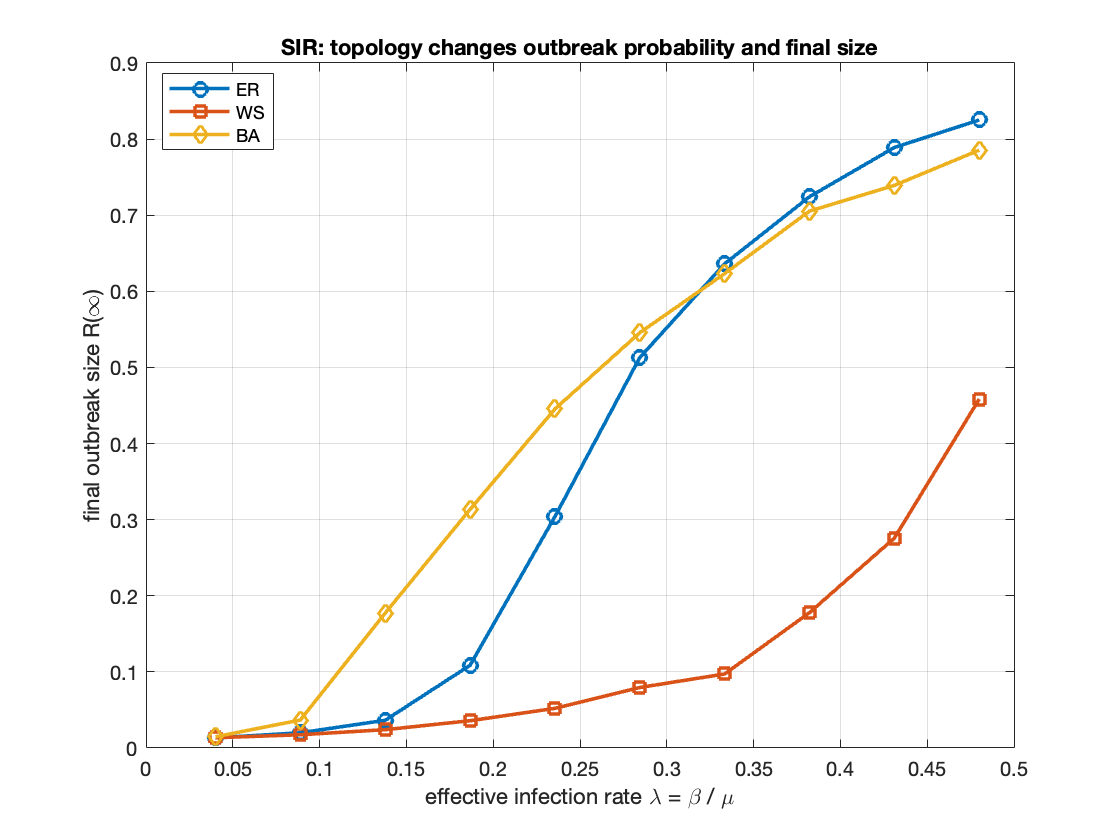

betaVals = linspace(0.01, 0.12, 10);
RinfER = zeros(size(betaVals));
RinfWS = zeros(size(betaVals));
RinfBA = zeros(size(betaVals));

runsSweep = 12;
Tfinal = 140;

for i = 1:numel(betaVals)
    b = betaVals(i);

    tmpER = 0;
    tmpWS = 0;
    tmpBA = 0;

    for r = 1:runsSweep
        [~, ~, R] = simulate_SIR_discrete(Ger, b, mu, Tfinal, seedFrac, 'random');
        tmpER = tmpER + R(end);

        [~, ~, R] = simulate_SIR_discrete(Gws, b, mu, Tfinal, seedFrac, 'random');
        tmpWS = tmpWS + R(end);

        [~, ~, R] = simulate_SIR_discrete(Gba, b, mu, Tfinal, seedFrac, 'random');
        tmpBA = tmpBA + R(end);
    end

    RinfER(i) = tmpER / runsSweep;
    RinfWS(i) = tmpWS / runsSweep;
    RinfBA(i) = tmpBA / runsSweep;
end

figure('Name', 'SIR final outbreak size vs infection rate');
plot(betaVals / mu, RinfER, 'o-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold on;
plot(betaVals / mu, RinfWS, 's-', 'LineWidth', 1.8, 'MarkerSize', 7);
plot(betaVals / mu, RinfBA, 'd-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold off;
xlabel('effective infection rate \lambda = \beta / \mu');
ylabel('final outbreak size R(\infty)');
title('SIR: topology changes outbreak probability and final size');
legend('ER', 'WS', 'BA', 'Location', 'best');
grid on;


fprintf('\nSIR demo finished.\n');


SIR demo finished.


fprintf('For the same approximate mean degree, final outbreak size and timing depend strongly on topology.\n\n');

For the same approximate mean degree, final outbreak size and timing depend strongly on topology.

